# 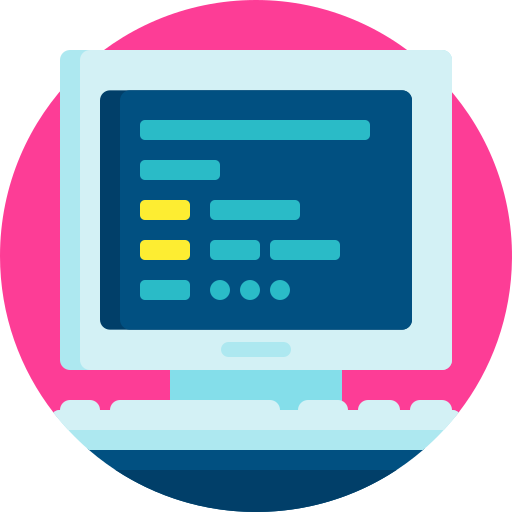

# Assignment 5 - Trajectory generation of a 2DOF manipulator arm

### This Assignment covers Section 4.4 of the Module A notes.

- This Assignment will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive (or on your PC if you are working on a laptop). 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on right`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (Windows) or CMD+ENTER (macOS).

Assignment 5 will build on the experience that you have gained from previous Assignments. It is now assumed that you are comfortable with the 2DOF manipulator and the accompanying MATLAB rigidBodyTree functionality.

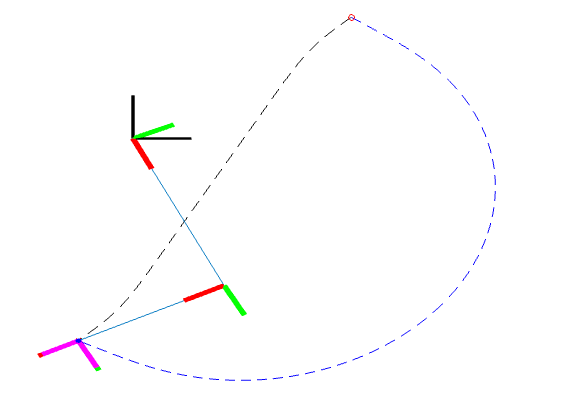

*Figure 1: Two different end-effector position trajectories that have common start and end points. The black trajectory is the result of a task space trapezoidal velocity profile, whereas the blue trajectory is a result of a joint space trapezoidal velocity profile.*

## Robot setup

Set up your 2DOF manipulator arm such that the link lengths are $l_1$=0.4m and $l_2=0.3$m, with joint rotations occuring about the $\hat{\bf z}$-axis. Set the joint home positions such that the end-effector is placed at $^W{\bf p}=[0.4~0.3]^T$. Use the same naming scheme as in the previous practicals and visualise the robot configuration to ensure that you have set everything up correctly. 

%Add robot setup code here
l1_ = 0.4;
l2_ = 0.3;

robot = rigidBodyTree("DataFormat","column");
manipulatorBase = rigidBody('manipulatorBase');
%joint1
joint1 = rigidBodyJoint('joint1','revolute');
joint1.JointAxis = [0 0 1];
joint1.HomePosition = 0;
p_joint1 = [0, 0, 0];
tform = trvec2tform(p_joint1);
setFixedTransform(joint1,tform)
manipulatorBase.Joint = joint1;
addBody(robot,manipulatorBase,'base');
%joint2 and link1
link1 = rigidBody('link1');
joint2 = rigidBodyJoint('joint2','revolute');
joint2.JointAxis = [0 0 1];
joint2.HomePosition = pi/2;
p_joint2 = [l1_, 0, 0];
tform2 = trvec2tform(p_joint2);
setFixedTransform(joint2,tform2);
link1.Joint = joint2;
addBody(robot,link1,'manipulatorBase');
%link2 and end-effector
link2 = rigidBody('link2');
joint3 = rigidBodyJoint('joint3');
tform3 = trvec2tform([l2_, 0, 0]);
setFixedTransform(joint3,tform3);
link2.Joint = joint3;
addBody(robot,link2,'link1');

Use `show `to ensure that the robot is correctly configured.

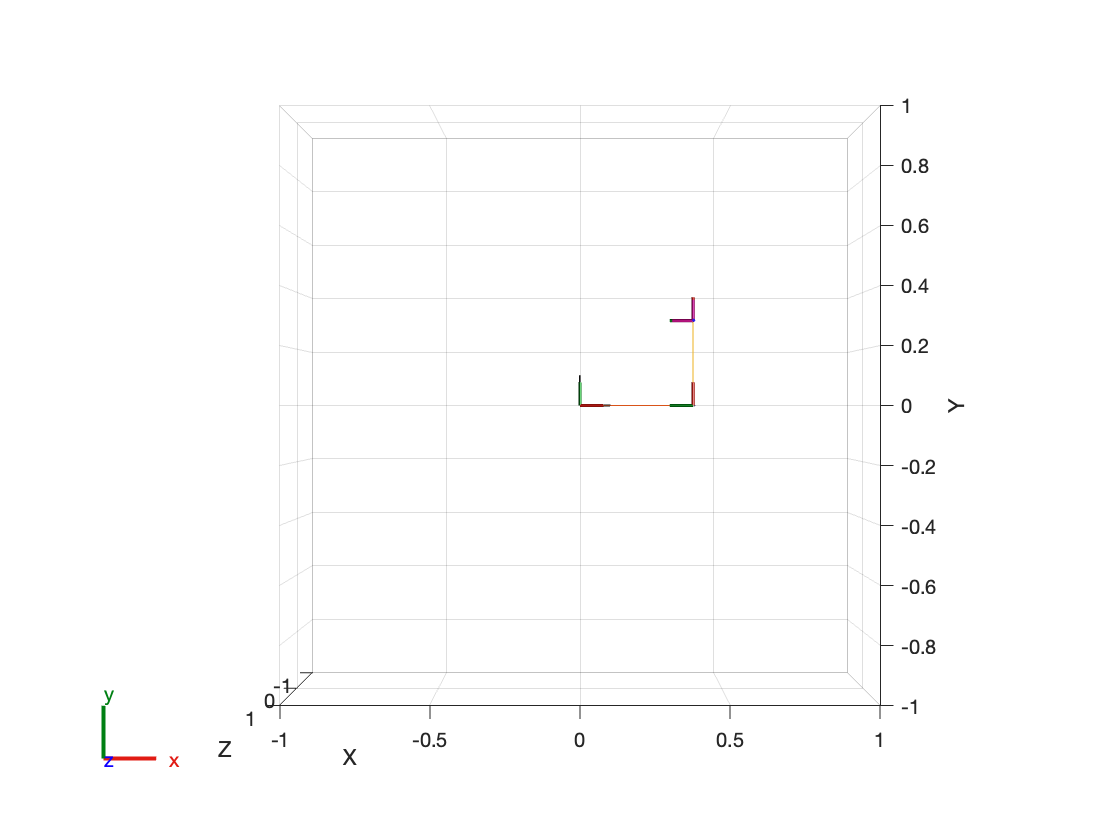

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%Add code here
figure
show(robot,homeConfiguration(robot)),view(2)

We will use $\bf q$ again as our generalised coordinate vector (it is not a quaternion!). Set $\bf q$ equal to the home configuration of the robot.

%Add code here
q = homeConfiguration(robot);


We will again make use of the closed-form (algebraic) inverse kinematic solution from Assignment 3 using the symbolic `solve` function. 

%Add code here
syms px py a b real
syms l1 l2 positive

[a,b] = solve( px==l1*cos(a)+l2*cos(a+b),py==l1*sin(a)+l2*sin(a+b),a,b);

a = simplify(expand(a));
b = simplify(expand(b));


We will use this later on in the Assignment, so do not overrite variables `a `and `b`!

## Trapezoidal velocity profiles

Trapezoidal velocity profiles are a useful means of defining trajectories when there are velocity and/or acceleration constraints that must be adhered to. 

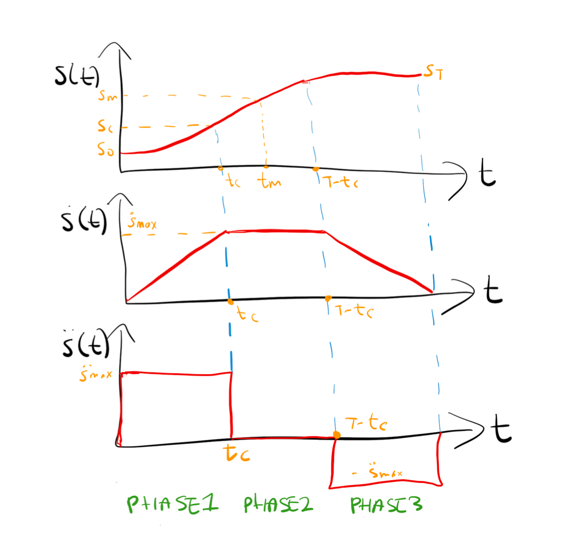

*Figure 2: Sketch of the position, velocity and acceleration trajectories that result from a trapezoidal velocity profile.*

Our task will be to command the robot such that the end-effector moves from the initial position of $^W{\bf p}=[0.4 ~0.3]^T$  to $^W{\bf p}^*=[-0.1 ~-0.5]^T$ in $1$ second. 

p_start = [0.4 0.3]';   %starting position of end-effector
p_end = [-0.1 -0.5]';   %end position of end-effector

Although the manipulator arm operates in a 2D translational space, we will develop a generic trapezoidal velocity function that operates in one dimension, which can then be used on each channel independently. In other words, each inertial-frame axis will have a different trapezoidal velocity profile that is used.

With reference to *Figure 2*, given an acceleration constraint of $\ddot{s}_{max}$, the position trajectory that results from a trapezoidal velocity profile is

$s(t)=\left\{
        \begin{array}{ll}
            s_0+\frac{1}{2}\ddot{s}_{max}t^2 & 0\leq t\leq t_c \\
            s_0+\ddot{s}_{max}t_c(t-t_c/2) & t_c < t\leq T-t_c \\
            s_T-\frac{1}{2}\ddot{s}_{max}(T-t)^2 & T-t_c\leq t\leq T \\
        \end{array}
    \right.$,

where $s_0$ is the starting position, $s_T$ is the end position, $t_c$ is the time value (in seconds) at the end of the first phase, and $t\in [0,T]$ is the time parameter in seconds. 

#### Question 1: Given the symmetrical requirement of trapezoidal velocity profiles, what is the largest possible $t_c$ value?

syms T 
t_c = T/2

$$t\_c = \frac{T}{2}$$

#### Question 2: What is the requirement on the maximum acceleration to ensure that a valid $t_c$ exists?

syms s_T s_0 dds_max
dds_max >= 4*abs(s_T-s_0)/T^2

$$ans = \frac{4\,\left|s_{0}-s_{T}\right|}{T^{2}}\leq {\mathrm{dds}}_{\max}$$

### Coding a trapezoidal velocity generator function.

Write a trapezoidal velocity trajectory function that has the following inputs 

- a 1x1 start point, $s_0$, 

- a 1x1 end point, $s_T$,

- a desired completion time, T,

- a maximum acceleration, $\ddot{s}_{max}$,

The function must output the position trajectory and corresponding derivatives. You must use a step size of $\Delta T$=1e$^{-3}$ seconds. 

Other considerations:

- If the maximum acceleration and completion time is incompatible, a display prompt should indicate this (see [`disp`](https://www.mathworks.com/help/matlab/ref/disp.html) function). 

- You can assume that the trajectory starts at $t=0$ seconds.

- Due to the fact that we are using a discretised profile, there will be certain combinations of input parameters that result in *minor* kinks where phases merge. This can be ignored.

- The desired completion time, $T$, can only have up to 3 decimal places. You will need to use [`round`](https://www.mathworks.com/help/matlab/ref/round.html) to enforce this in the function.

You can write the function in a seperate `MATLAB .m` file (saved in the same folder as `Assignment5.mlx`) or at the bottom of the Assignment 5 live script. The function should have the general structure and naming convention as shown below:

Once you have written your function call it in the code block below, using the following configuration

- $|\ddot{s}_{max}|=4$ $m/s^2$,

- $T=1$second,

- $s_0=0.4$ metres,

- $s_T=-0.1$.

Note that this is the end-effector requirement in the $\hat{x}$-axis.

%Add code here
T = 1;
s0 = p_start(1);
sT = p_end(1);
dds_max = 4;
[s,ds,dds] = getTrapezoidalTrajectory(s0,sT,T,dds_max);

Plot the three profiles using `subplot`*,* and set the figure title as your name+student number using `sgtitle` (see *Figure 3* below as an example).

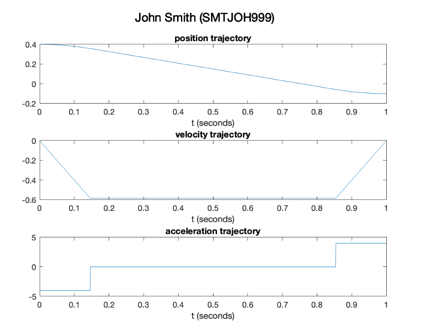

*Figure 3: An example of using subplot to display the position, velocity and acceleration trajectories.*

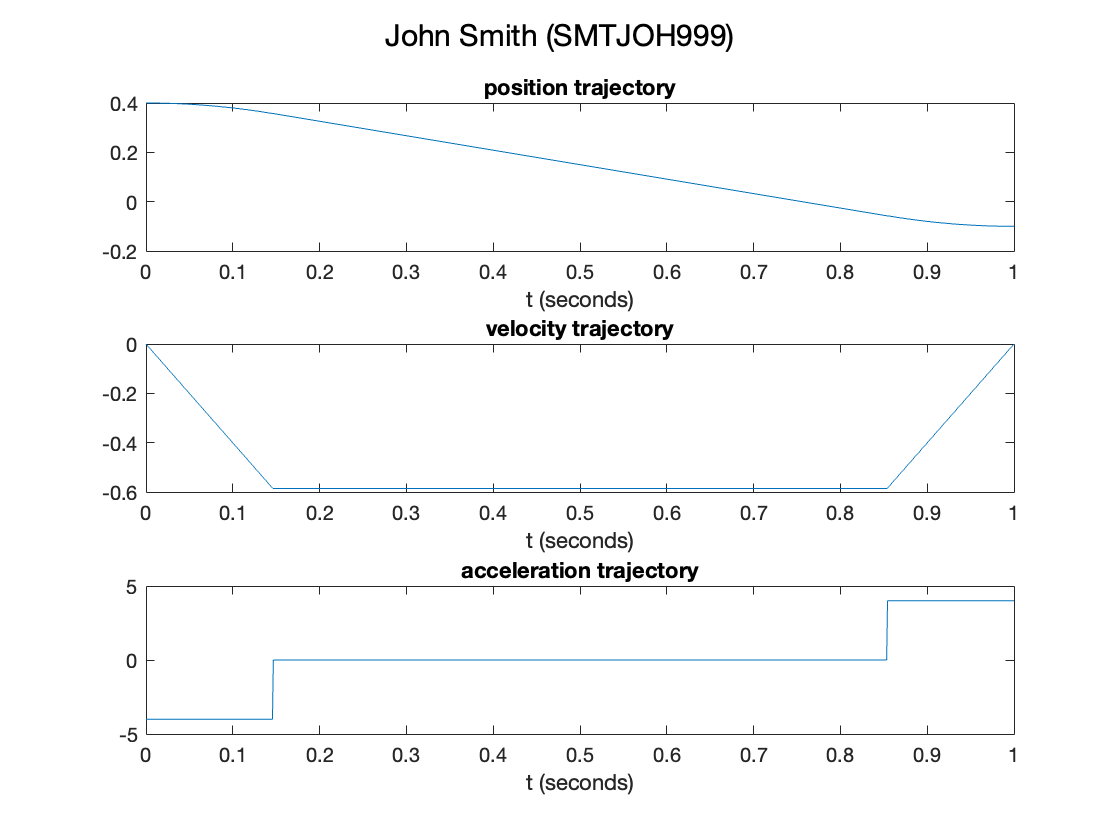

%Add code here
t = linspace( 0,T,length(s) );

figure(1),clf,shg,hold on
subplot(3,1,1),plot(t,s),xlim([0 T]),title('position trajectory'),xlabel('t (seconds)')
subplot(3,1,2),plot(t,ds),xlim([0 T]),title('velocity trajectory'),xlabel('t (seconds)')
subplot(3,1,3),plot(t,dds),xlim([0 T]),title('acceleration trajectory'),xlabel('t (seconds)')
sgtitle('John Smith (SMTJOH999)')

shg

#### Question 3: Upload your `subplot` figure (jpeg/png) from above.

If your answer is correct, it should match that of *Figure 3*.

#### Question 4: What is the minimum possible completion time for this particular trajectory, given the acceleration limit?

*Hint: test your minimum completion time with your trapezoidal trajectory generator function.*

%Add code here.
sT = p_end(1);
s0 = p_start(1);
T_min = sqrt( 4*abs(sT-s0)/dds_max )

T_min = 0.7071

#### Question 5: Upload a hand-drawn sketch (or MATLAB-generated image) of the position, velocity, and acceleration profiles when using the minimum completion time for Question 4.

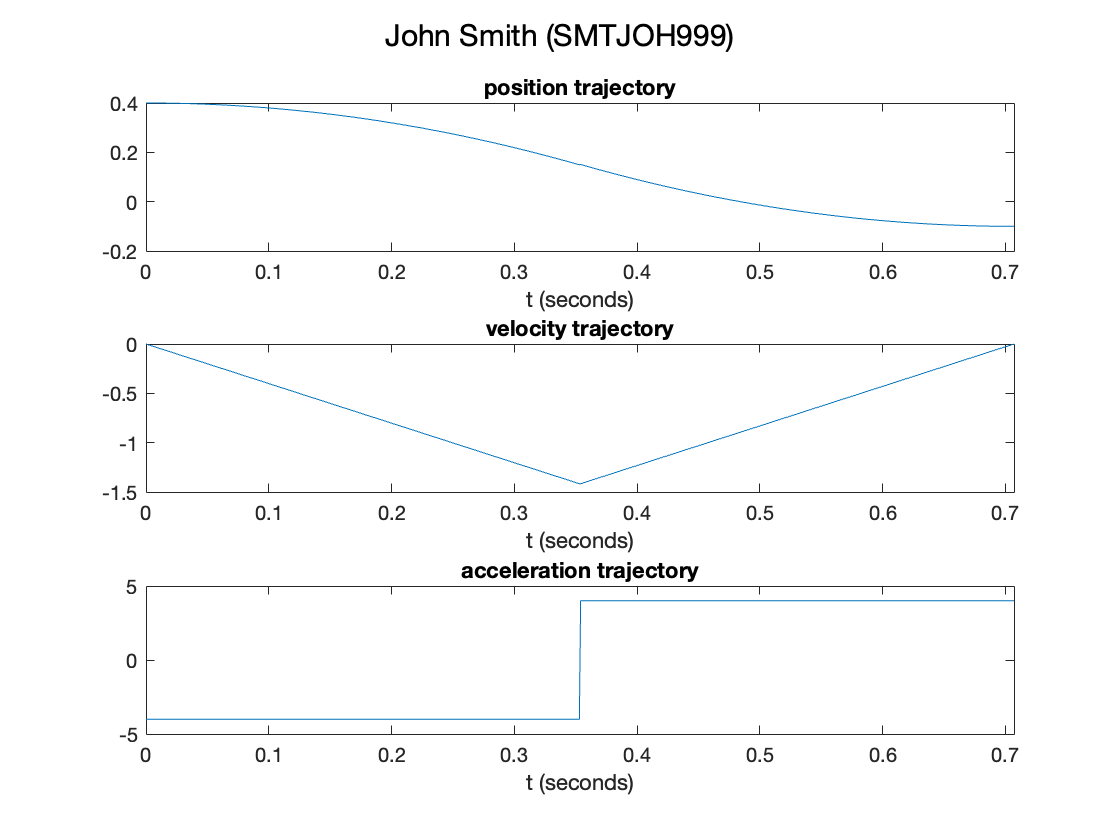

%Add code here
T = T_min;
[s,ds,dds] = getTrapezoidalTrajectory(s0,sT,T,dds_max);

t = linspace( 0,T,length(s) );

figure(1),clf,shg,hold on
subplot(3,1,1),plot(t,s),xlim([0 T]),title('position trajectory'),xlabel('t (seconds)')
subplot(3,1,2),plot(t,ds),xlim([0 T]),title('velocity trajectory'),xlabel('t (seconds)')
subplot(3,1,3),plot(t,dds),xlim([0 T]),title('acceleration trajectory'),xlabel('t (seconds)')
sgtitle('John Smith (SMTJOH999)')

shg

## Task space trajectory following

Adjust your animation code from **Assignment 3** to use the trajectory generator function to set the end-effector position using inverse kinematics. You will need to apply the function to each position component individually (e.g. generate separate trajectories for $p_x$ and $p_y$).  Remember that you have already defined the `robot` object and inverse kinematic mapping at the beginning of the Assignment.

- Plot the 2D path that the end-effector must take using a black dashed line. 

- Use a completion time of $T=1$second. 

- Your trajectory will have time increments of $\Delta T=0.001$seconds, but update the plot every 0.1 seconds (every $100$th iteration). 

- Use the same starting configuration and maximum acceleration as above.

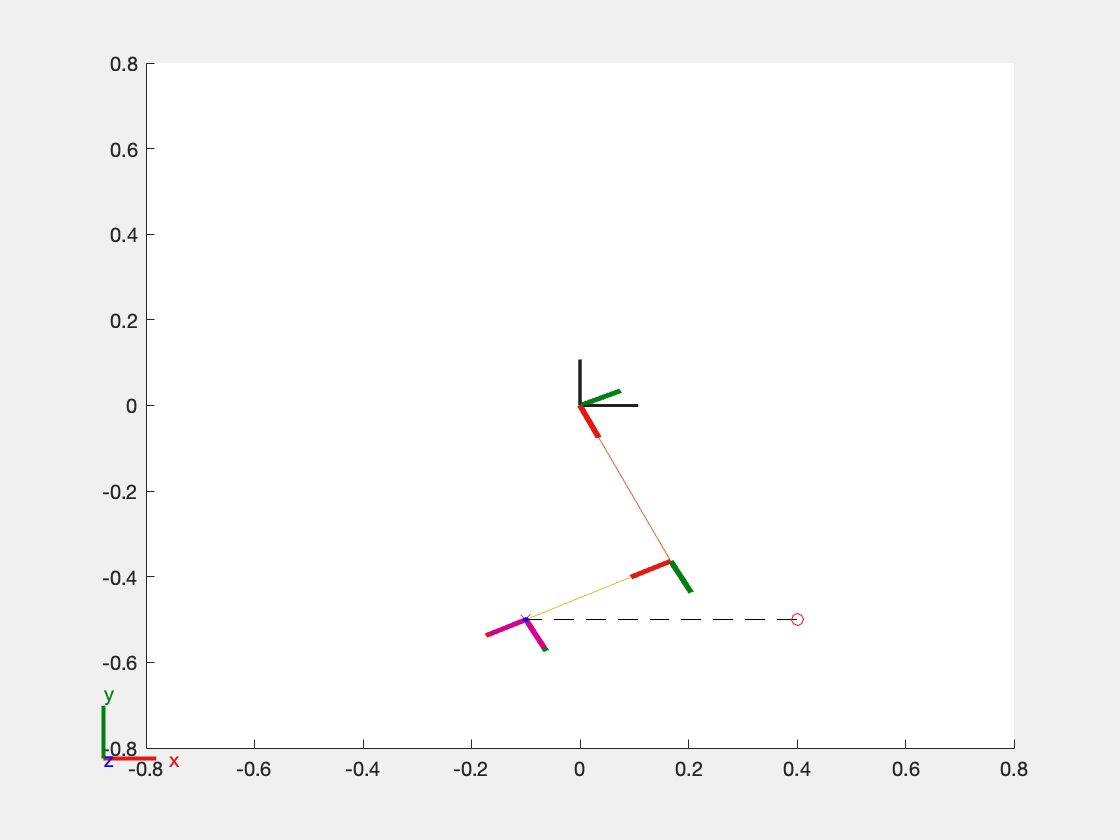

%Add code here
dT = 0.1;

video = VideoWriter('Q4','MPEG-4'); 
video.FrameRate = 1/dT;  
open(video)

l1 = l1_;
l2 = l2_;

q=homeConfiguration(robot);

h = figure;
set(h,'WindowStyle','modal','name','2DOF manipulator','numbertitle','off')
hold on
axis([-0.8 0.8 -0.8 0.8])

timer = rateControl(1/dT);

dds_max = 4;
[sx,dsx,ddsx] = getTrapezoidalTrajectory(p_start(1),p_end(1),T,dds_max);
[sy,dsy,ddsy] = getTrapezoidalTrajectory(p_end(2),p_end(2),T,dds_max);
s_p = [sx;sy];

plot(s_p(1,:),s_p(2,:),'--k')
plot(s_p(1,1),s_p(2,1),'ro')
plot(s_p(1,end),s_p(2,end),'rx')

cnt = 0;
for i=1:length(s_p(1,:))   

    cnt=cnt+1;
    if(cnt==100)
        cnt=0;

        px = s_p(1,i);
        py = s_p(2,i);
        a_ = eval(a);
        b_ = eval(b);

        q(1) = a_(1);
        q(2) = b_(1);

        show(robot,q,'Collisions','on','Visuals','off','PreservePlot',false);
        view(2)

        drawnow

        frame = getframe(gcf); %get frame
        writeVideo(video, frame);

        waitfor(timer);
    end
end

close(video)

You should see the end-effector move smoothly from the start configuration to the end configuration in a "straight-ish" line as shown below

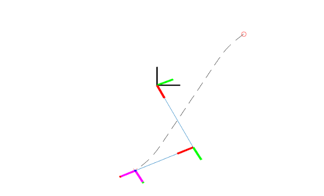

*Figure 4: End-effector reaching end position after moving along task space trajectory.*

#### Question 6: Explain why the 2D path that the end-effector takes is not a straight line.

*Hint: Plot the trapezoidal velocity trajectories of *$\dot{p}_x$ and $\dot{p}_y$ on the same graph 

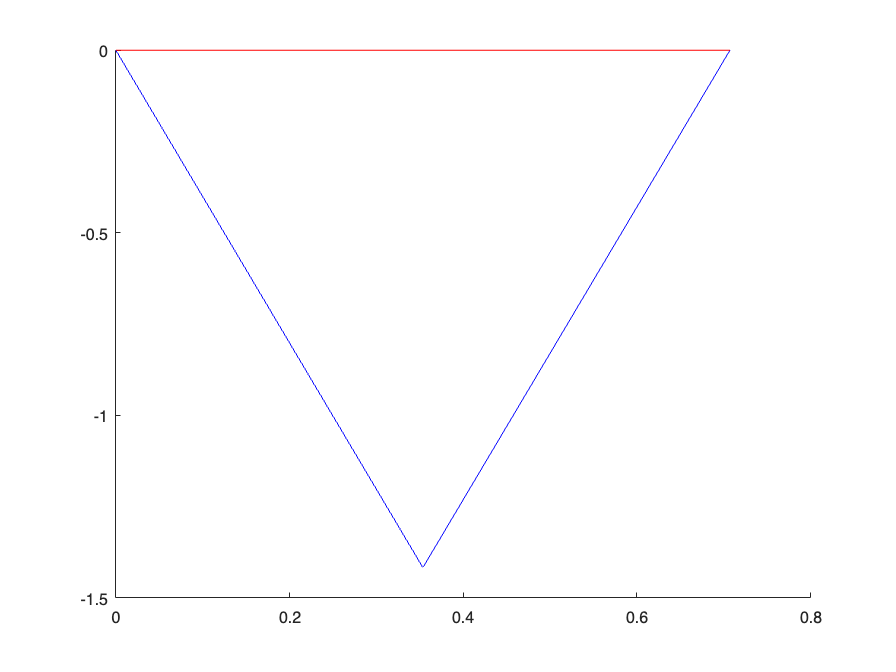

%Add code here
figure,hold on
t = linspace(0,T,length(dsx));
plot(t,dsx,'b-')
plot(t,dsy,'r-')

Add to your animation code in order to record a .mp4 of the animation. This can be done by adding

before the `loop`, adding

after `drawnow`, and adding 

after the loop.

#### Question 7: Upload a .mp4 of the end-effector moving along the defined trajectory.

## Configuration space trajectory following

Based on **Assignment 3**, it should not be surprising that we can define and follow trajectories within the end-effector workspace. What is less obvious is whether any workspace trajectory can be followed given actuator limitations (e.g. joint rate and acceleration limits). 

If we are not concerned with the exact path that the end-effector takes, and are only concerned with the start and endpoints, we can rather develop a configuration (joint) space trajectory using trapezoidal velocity profiles (and our known actuator limits), in order to ensure that our robot can always follow the path. We can start by mapping the start and end points of the task space trajectory into the configuration space.

q_start = homeConfiguration(robot);

px = p_end(1);
py = p_end(2);
a_ = eval(a);
b_ = eval(b);

q_end = [a_(1) b_(1)]; %we will use the first set of solutions.


 `q_start` and `q_end` now define the start and end configurations of our joint space trajectory and we can now use a trajectory generation routine to link the two. Note that regardless of the specific type of trajectory, once our robot configuration is `q_end`, our end-effector position will be at $^W{\bf p}^*$ by definition of our unique forward kinematic relationship

${^W{\bf p}^\ast}={\bf\kappa}(q_{end})$.

Similarly, `q_start `will always map to ${^W{\bf p}=[0.4~0.3]^T$, based on the use of the `homeConfiguration `in the code block above. 

We will now use our trapezoidal velocity trajectory function to generate a trajectory for both joint angles. Adjust your visualisation code from before to set the required joint angles directly based on the generated trajectory (no longer using inverse kinematics, but using the start and end configurations from above as your start and end points for the trajectory generator). You will need to apply the function to each required joint angle individually. 

- Plot the path that the end-effector takes using a blue dashed line. 

- Also plot the end-effector position trajectory from the previous question (in a black dashed line). 

- Your trajectory will have time increments of $\Delta T=0.001$seconds, but update the plot every 0.1 seconds (every $100$th iteration). 

- Use a completion time of $T=1$second. 

- Use an angular acceleration limit of $\ddot{s}_{max}=20$rad/s$^2$ for both joint angles   

%Add code here

currentFolder = pwd;
filename = [pwd,'/','Q7.gif']

filename = '/Users/arnoldpretorius/Library/CloudStorage/OneDrive-UniversityofCapeTown/Documents - MMT Stream/General/MEC4127F - Mechatronic Systems/Assessments/Assignments/Assignment 5/Q7.gif'

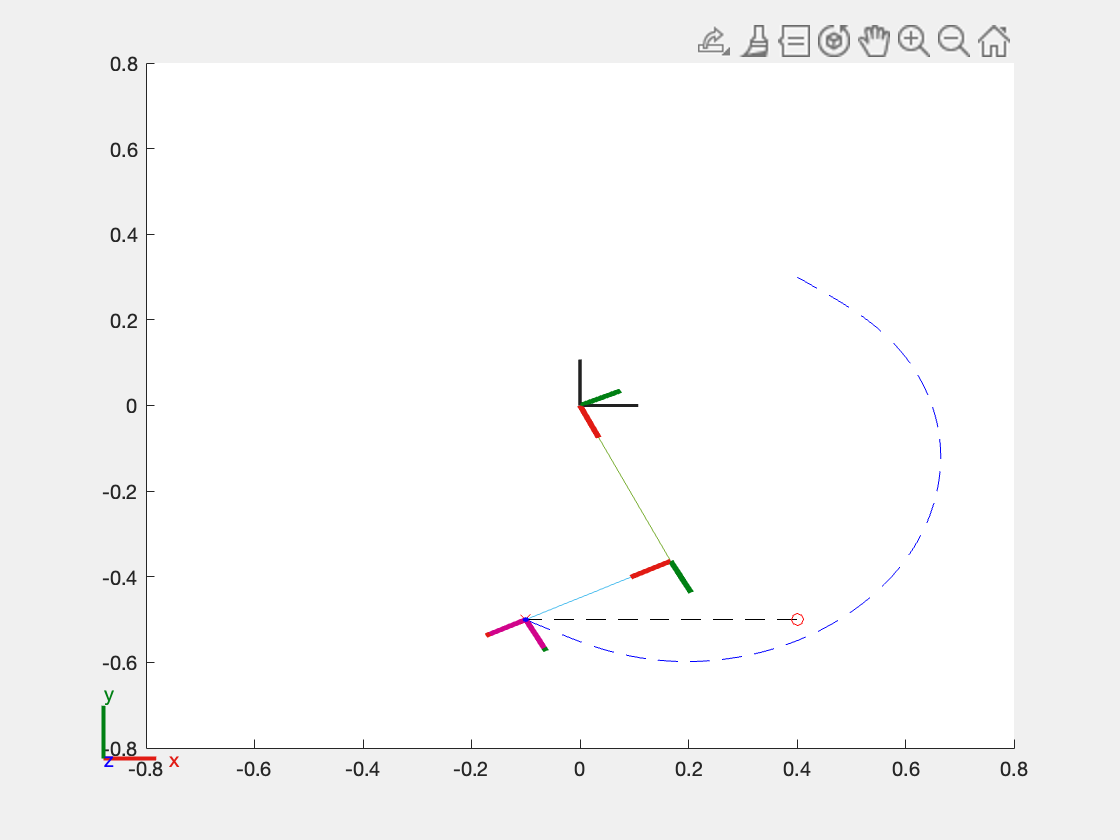


q=homeConfiguration(robot);

dT = 0.1;
rc = rateControl(1/dT);

T = 1;
dds_max = 20;

[s1] = getTrapezoidalTrajectory(q_start(1),q_end(1),T,dds_max);
[s2] = getTrapezoidalTrajectory(q_start(2),q_end(2),T,dds_max);

s_q = [s1;
    s2];

h = figure;
set(h,'WindowStyle','modal','name','2DOF manipulator','numbertitle','off')
hold on
axis([-0.8 0.8 -0.8 0.8])

plot(l1_*cos( s_q(1,:) )+l2_*cos( s_q(1,:)+s_q(2,:) ),l1_*sin( s_q(1,:) )+l2_*sin( s_q(1,:)+s_q(2,:) ),'--b')
plot(s_p(1,:),s_p(2,:),'--k')
plot(s_p(1,1),s_p(2,1),'ro')
plot(s_p(1,end),s_p(2,end),'rx')

cnt=0;
for i=1:length(s1)

    cnt=cnt+1;
    if(cnt==100)
        cnt=0;

        q(1) = s1(i);
        q(2) = s2(i);
        show(robot,q,'Collisions','on','Visuals','off','PreservePlot',false);
        view(2)

        drawnow

        frame = getframe;
        im = frame2im(frame);
        [imind,cm] = rgb2ind(im,256);
        if i == 100
            imwrite(imind,cm,filename,'gif', 'Loopcount',inf,'DelayTime',dT);
        else
            imwrite(imind,cm,filename,'gif','WriteMode','append');
        end

        waitfor(rc);
    end
    %     waitfor(rc);
end

If your simulation is correct, the final configuration and image should match that of *Figure 1 *and the end-effector should move smooth smoothly along the blue path.

#### Question 8: Upload a .mp4 of the animation in Vula.

#### **Question 9: What maximum acceleration would be required for **`elbowJoint`** if the completion time is **$T=0.75$** seconds?**

%ANSWER
dds_max = 4*abs(q_end(2)-q_start(2))/.75^2 %rad/s/s

dds_max = 22.0438

The result of defining joint space trajectories means that "straight-ish" lines in the configuration space map to arcs in the task space. However, the benefit of joint space trajectories is that we are directly taking into account the actuator limitations. Note that our configuration took the same time to complete, albeit with completely different spatial paths! Specifying trajectories in the task space is appealing if we need to navigate around obstacles (or move in approximately straight lines), whereas joint space trajectories are useful if we have strict acuator limits that we need to adhere to.

#### Question 10: Upload your .mlx or .m file in Vula.